# Convert PGM Image to Map

Convert a portable graymap (PGM) file containing a  map into an `occupancyMap` for use in MATLAB®.

Import the image using `imread`. Crop the image to the playpen area.

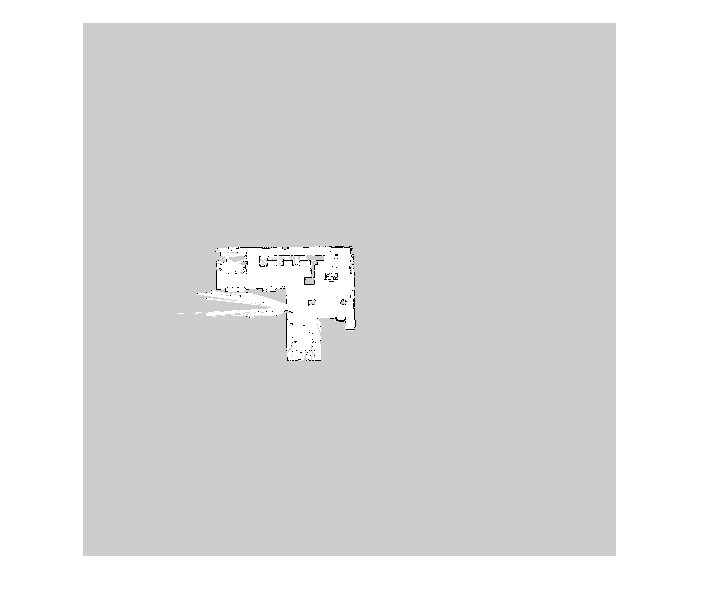

image = imread('././My_Workspace/Coding Works/robotino_project/src/nav/ConvertPGMImageToMapExample/iot.pgm');
imshow(image)

PGM values are expressed from 0 to 255 as `uint8`. Normalize these values by converting the cropped image to `double` and dividing each cell by 255. This image shows obstacles as values close to 0. Subtract the normalized image from 1 to get occupancy values with 1 representing occupied space.

imageNorm = double(image)/255;
imageOccupancy = 1 - imageNorm;

Create the `occupancyMap` object using an adjusted map image. The imported map resolution is 20 cells per meter.

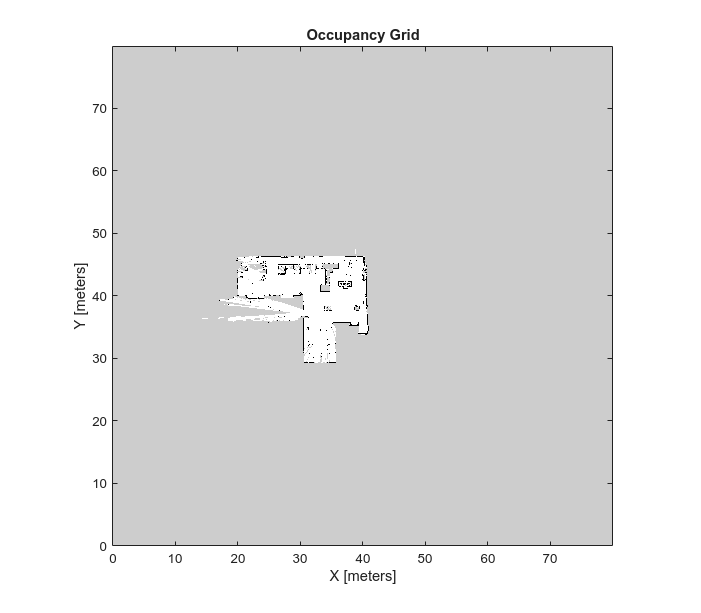

map = occupancyMap(imageOccupancy,20);
show(map)

save('././My_Workspace/Coding Works/robotino_project/src/nav/ConvertPGMImageToMapExample/IOTFactoryOccupancyGridMap.mat', 'map');

*Copyright 2019 The MathWorks, Inc.*